# Event distance analysis (arena events)

### 1 Simplify events by removing M duplicates and selecting specified K 

If multiple events are significant starting at the same time for the same length, only keep the one with highest number of neurons 

% get simplified events and antievents
load('em_arena_th0.5.mat')
em=rem_dup_em(em);
[N,nm]=size(em{1,1}.eve);

Find events with 4 specified lengths: 5s, 20s, 40s, 100s 

klist={5,20,40,100};% find events separately for each k
% events
for r=1:2 % two rounds 
    allt=cell(N,nm);allm=cell(N,nm);allk=cell(N,nm);
    for p=1:N
        for m=1:nm
            [allt{p,m},allm{p,m},allk{p,m}]=alltmk(klist,em{r,1}.K{p,m},em{r,1}.M{p,m},em{r,1}.time{p,m});
        end
    end
    em{r,1}.allt=allt;em{r,1}.allm=allm;em{r,1}.klist=klist;em{r,1}.allk=allk;
end

### Calculate distance between events for each k 

For each event in one animal, calculate the distance between the center of this event and the nearest event in the other animal. 

Get within pair distance for each event and between pair distance for each event 

% merge events from the two rounds of detection 
ev_merge=cell(N,nm); % center of all events 
for p=1:N
    for m=1:nm
        ev_merge{p,m}=cell(1,4);
        for k=1:4
            % merge events from the two rounds of detection 
            ev_merge{p,m}{k}=combine_2_r(em{1,1}.allt{p,m}{k},find(em{2,1}.timefilter{p,m}),em{2,1}.allt{p,m}{k},'position','center',"k",klist{k});
            ev_merge{p,m}{k}=remove_time_ovp(ev_merge{p,m}{k},klist{k}); % remove highly overlapped events
        end
    end
end
% within-pair distance
distwithin=cell(N,nm);distbetween=cell(N,nm);
for p=1:N
    for m=1:2
        distwithin{p,m}=cell(1,4);distbetween{p,m}=cell(1,4);
        for k=1:4
            if isempty(ev_merge{p,m}{k})
               continue 
            end
            % within pair
            distwithin{p,m}{k}=eventdist(ev_merge{p,m}{k},ev_merge{p,setdiff([1 2],m)}{k}); 
            distbetween{p,m}{k}=[];
            for p1=setdiff(1:N,p) % exclude the same pair index
                for m1=1:2
                    if isempty(ev_merge{p1,m1}{k})
                        continue 
                    end
                    distbetween{p,m}{k}(end+1,:)=eventdist(ev_merge{p,m}{k},ev_merge{p1,m1}{k}); 
                end
            end
        end
    end 
end

### Plot distribution of event distance 

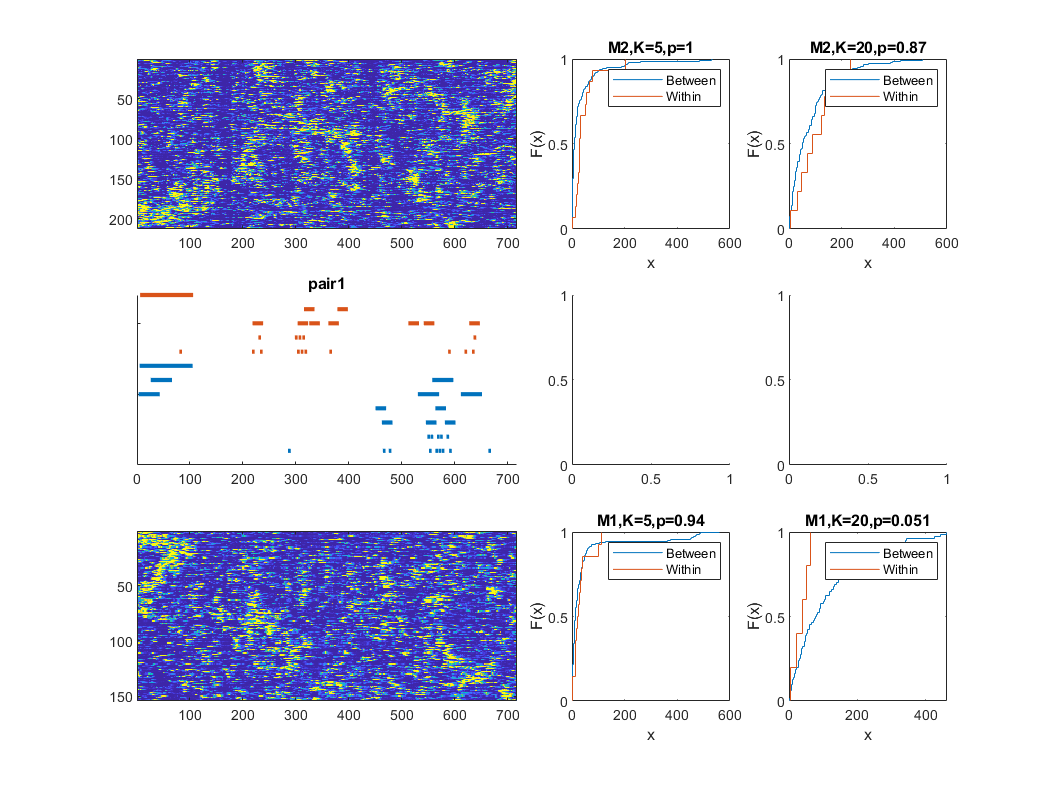

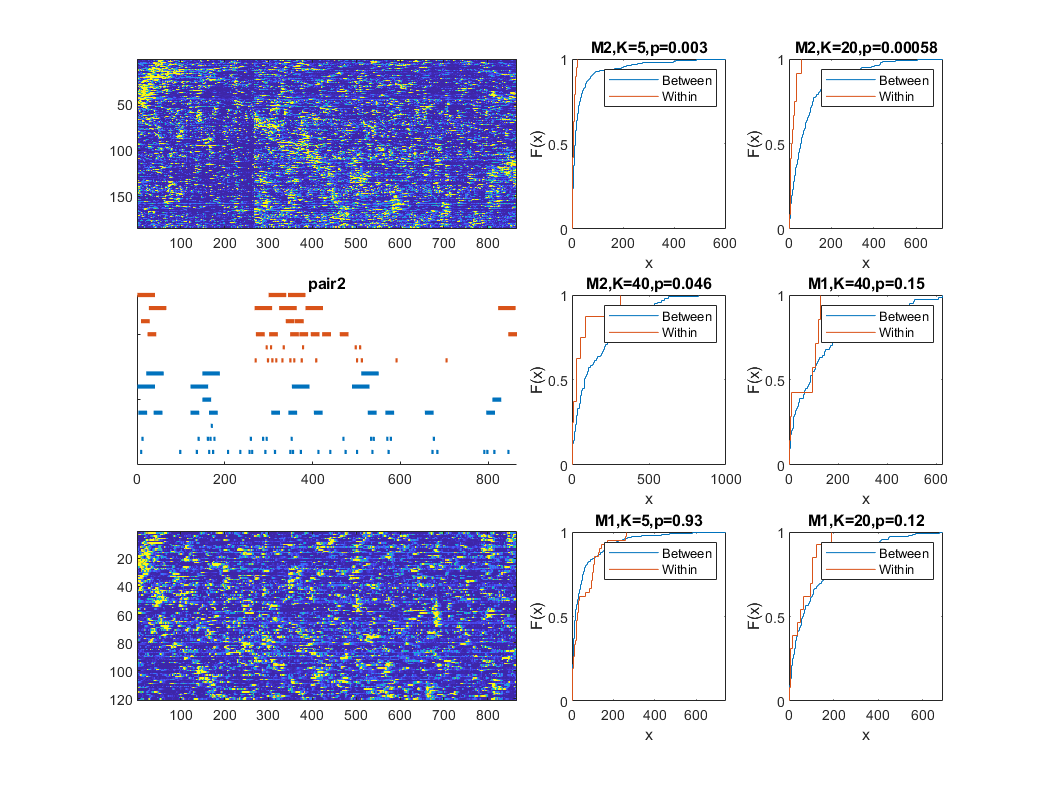

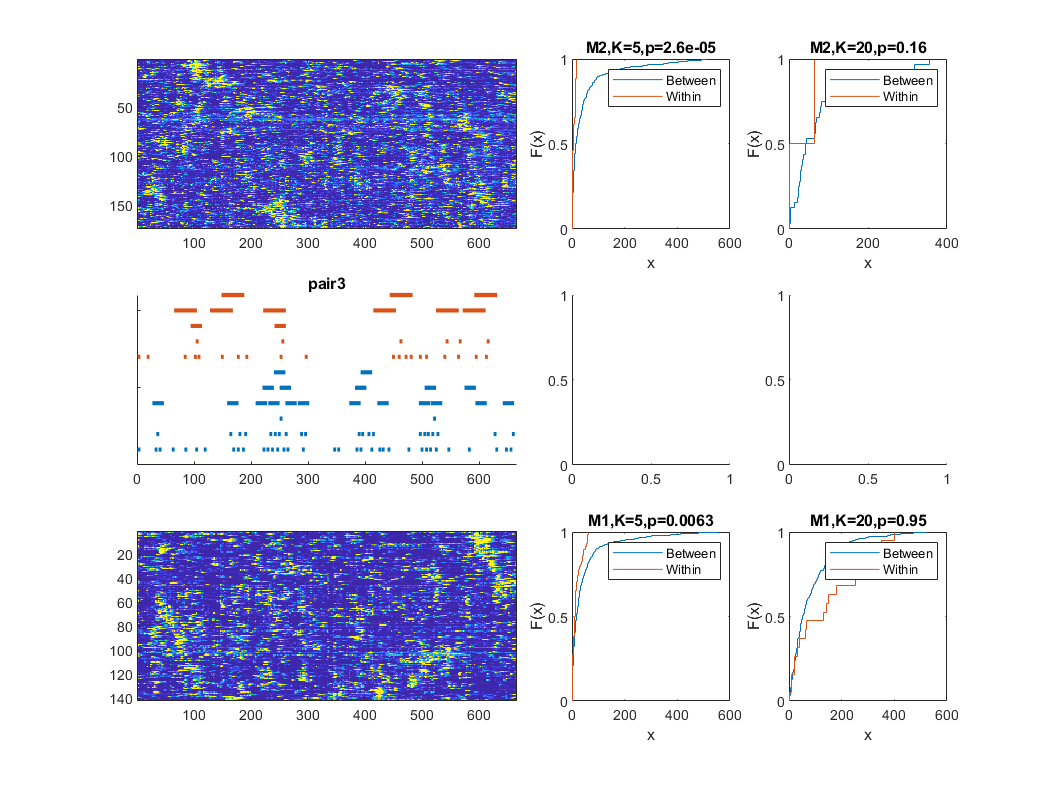

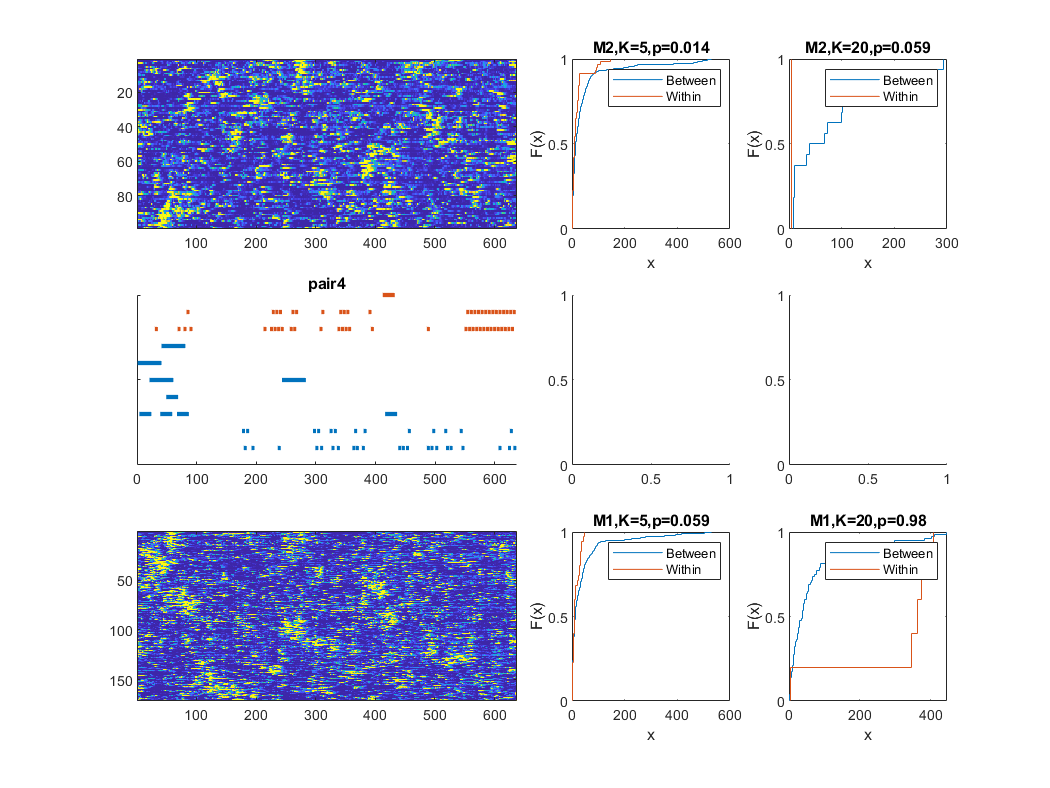

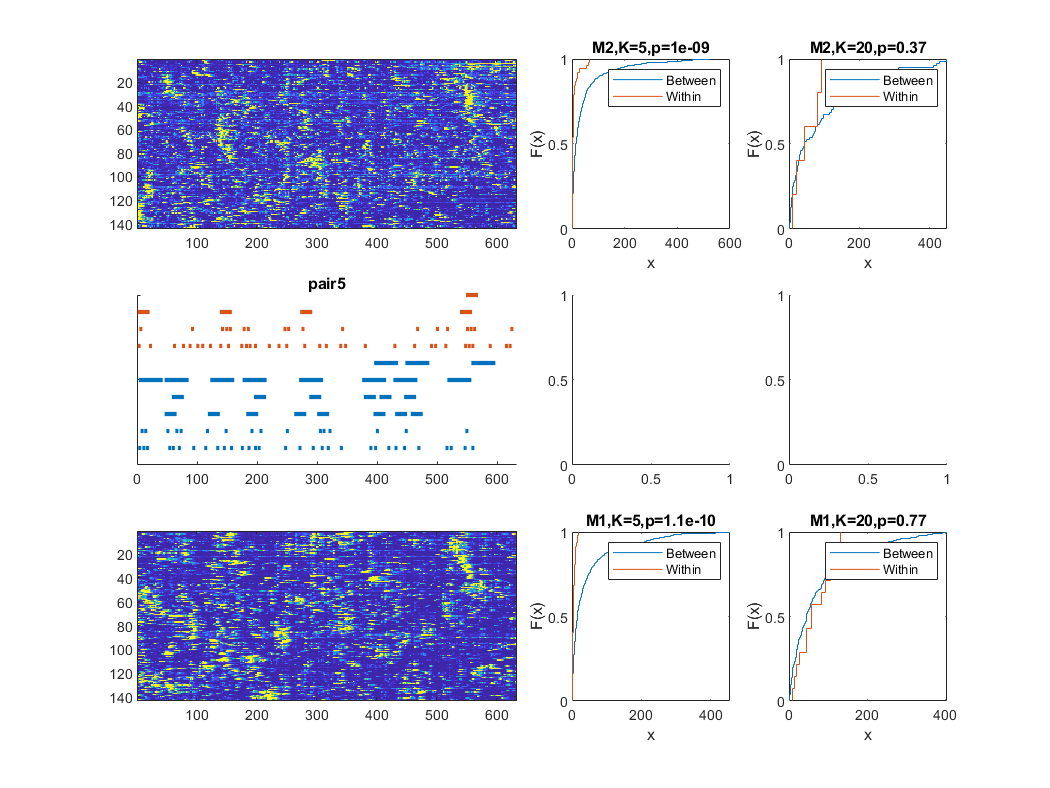

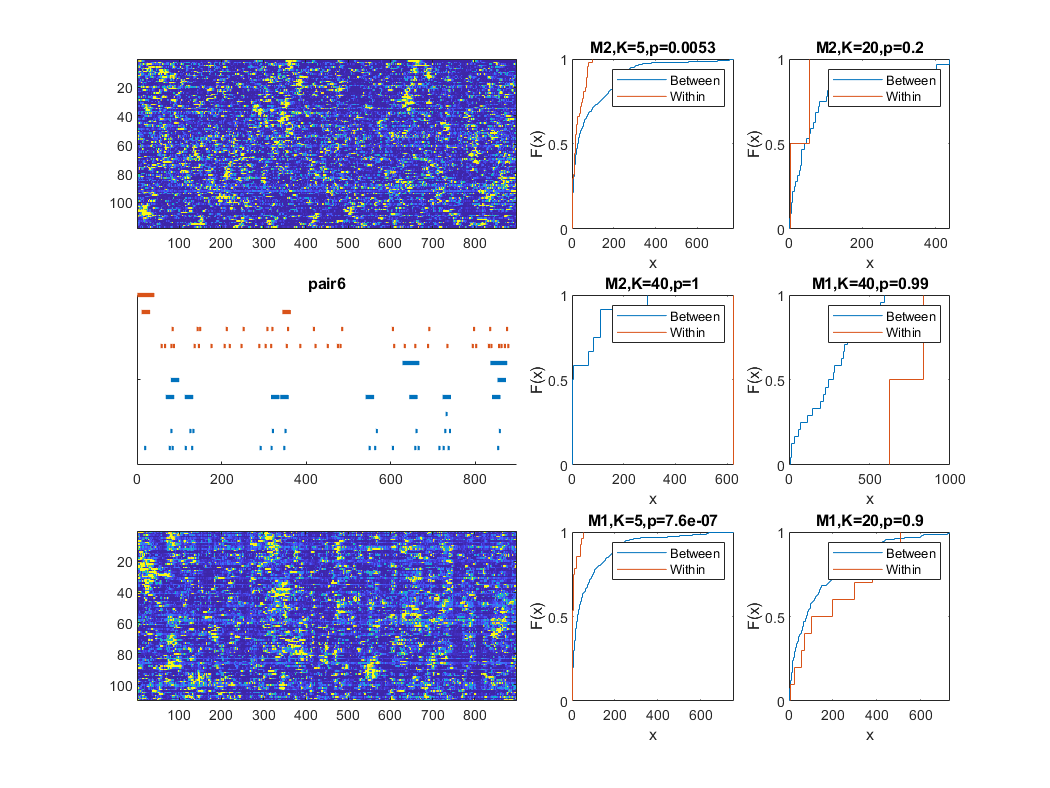

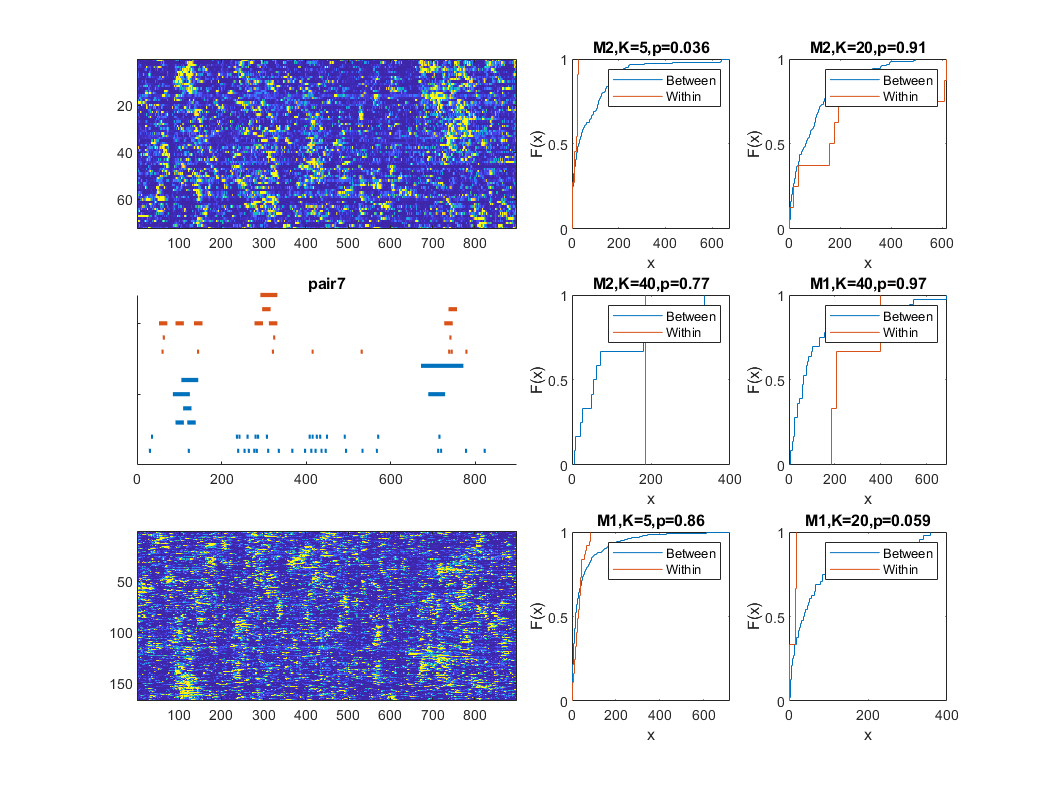

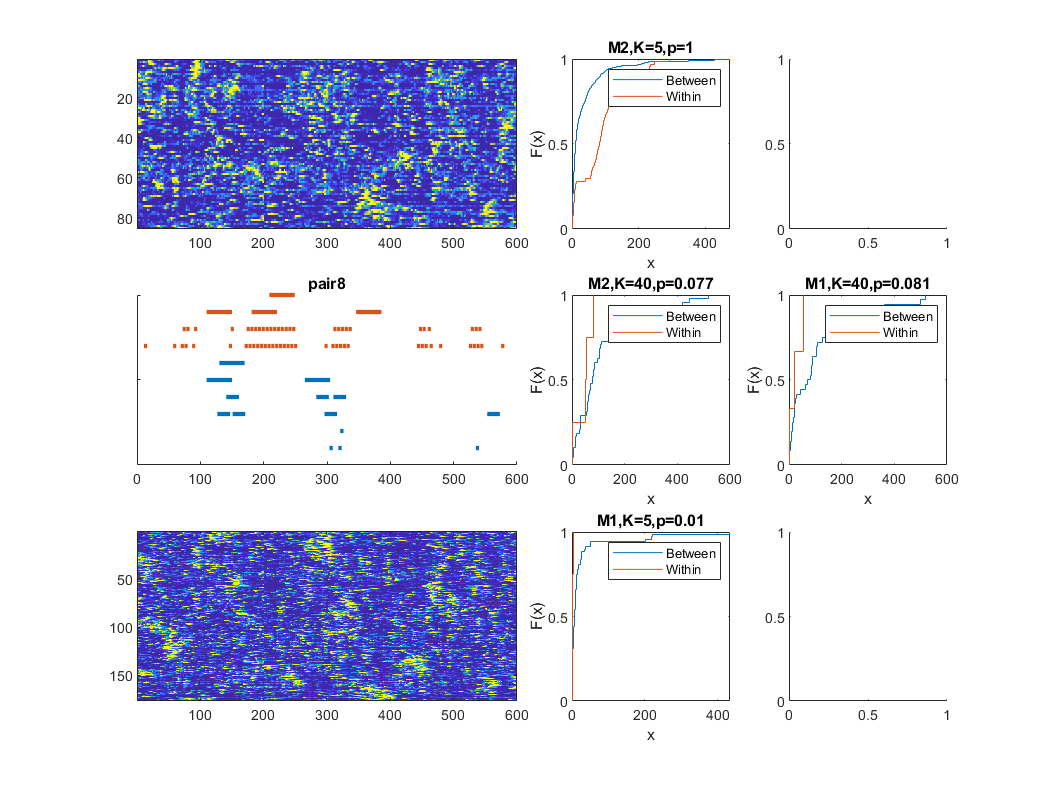

rs=NaN(3,N,nm);
close all 
for p=1:N
    f=figure;f.Position(3)=2*f.Position(4);f.Position(4)=1.5*f.Position(4);
    [rs(:,p,:)]=constitutional_eventplot_arena(em,klist,ev_merge,distwithin,distbetween,p);
end

### Summary of All Mice 

rs=reshape(rs,3,[]);
smy=[sum(rs'<=0.05);sum(~isnan(rs'))];
array2table(smy,"RowNames",{'nSignificant','nData'},'VariableNames',{'K=5','K=20','K=40'})

ans = 2×3 table
                    K=5    K=20    K=40
                    ___    ____    ____

    nSignificant    11       3       1 
    nData           18      16      10 
